# Iterative calculation of the Convection Heat Transfer Coefficient 

This livescript is divided in two parts:

Part 1: calculate the convection heat transfer coefficient between between the brake rotor and the air stream for different speeds, using empirical correlations found in the literature. This estimate can be used for initial design stages to evaluate the temperature rise of the brake rotors. 

Part 2: a simple model is used to calculate the temperature rise on the brake rotor during a hard braking maneuver, for different materials that could be used to manufacture disc brakes.

Author: Luis Daniel Medina Querecuto

luisdamed@gmail.com

Date: 17/11/2019

References: 

[1] Incropera, F.,De Witt, David. "*Fundamentals of Heat and Mass Transfer, 6th Edition". *Prettice Hall. **ISBN-13:** 978-0470055540

[2] R. Limpert, Brake Design and Safety, Warrendale, PA.: Society of Automotive Engineers, Inc., 1999. **ISBN-13:** 978-1560919155

[3] B. Latour, P. Bouvier and S. Harmand, "Convective Heat Transfer on a Rotating Disk With Transverse Air Crossflow," *Journal of Heat Transfer, *vol. 133, pp. 021702-1 -10, 2011. DOI: 10.1115/1.4002603

 clc, clear all, close all

## Input data

Disc_data

V_disc = 5.4432e-05

w_pad = 0.0498

S_p = 0.0015

t_pad = 0.0040

S_d = 0.0163

load Air_props.mat 
m= 270; %car mass in kg
Speed=70; %car speed in km/h
V_i= Speed/3.6 %Initial Vehicle Speed [m/s]

V_i = 19.4444

V_f=0 %Final Vehicle Speed [m/s]

V_f = 0

R_wheel=0.217 %Wheel Radius [m]

R_wheel = 0.2170

V_inst=linspace(V_i,V_f,100); %Average Car speed in braking maneuver [m/s]
r=linspace(r_disc-h_disc,r_disc,10)

r =     0.0790    0.0823    0.0857    0.0890    0.0923    0.0957    0.0990    0.1023    0.1057    0.1090


Decel_avg=1.8*9.81 %Average deceleration in [m/s^2]

Decel_avg = 17.6580

% alpha_avg=Decel_avg/(r_disc-0.5*h_disc); %Average angular deceleration of the disc in [rad/s^2]
Brake_bias=0.68; %brake distribution on the axle of study
Brake_pressure=35; %Brake pressure [bar]
mu_pad=0.8;
D_piston=24; %Piston diameter in mm
N_piston=4; %Number of pistons
A_piston= N_piston*pi*(D_piston/2)^2

A_piston = 1.8096e+03

F_normal=0.1*Brake_pressure*A_piston %Normal force between pads and rotor [N]

F_normal = 6.3335e+03

Brake_torque=mu_pad*F_normal*(r_disc-h_pad) % Brake torque applied to the rotor [Nm]

Brake_torque = 400.2741

t_stop= (V_i-V_f)/Decel_avg

t_stop = 1.1012

dstop=(V_i^2-V_f^2)/(2*Decel_avg) %distance covered during braking in meters

dstop = 10.7058

CxS=1.12; %Aerodynamic drag
materials=6; %Define the number fo materials to compare. The properties are defined in Mat_properties.m
i=1;


## Iteration cycle

This loop calculates the convection coefficients for varying wheel speeds.

omega=zeros(1,length(V_inst));
for i=1:length(V_inst)
    
        omega(i)=V_inst(i)/R_wheel; %Wheel angular speed [rad/s]
        
        %-----------Initial Thermal Parameters------------------------------------
        %Air Properties vs Temperature
        T_disc(i)=400+273.15; %Input brake disc temperature [K]. Assumed or estimated value
        T_air=30+273.15; %Air Temperature [K]
        T_film(i)=(T_air+T_disc(i))/2; %Film Temperature [K]
        
        %Thermal properties of the current iteration
       
        rho_air(i) = interp1(Air_props.Temp,Air_props.Density,T_air-273.15);    %Air density at air temperature [kg/m3]
        rho_air_f(i) = interp1(Air_props.Temp,Air_props.Density,T_film(i)-273.15); %Air density at film temperature [kg/m3]
        rho_air_s(i) = interp1(Air_props.Temp,Air_props.Density,T_disc(i)-273.15); %Air density at surface temperature [kg/m3]
        
        mu_air(i) = interp1(Air_props.Temp,Air_props.Dyn_Visc,T_air-273.15); %Air Dynamic viscosity at air temperature [kg/ms]
        mu_air_f(i) = interp1(Air_props.Temp,Air_props.Dyn_Visc,T_film(i)-273.15); %Air Dynamic viscosity at film temperature [kg/ms]
        mu_air_s(i) = interp1(Air_props.Temp,Air_props.Dyn_Visc,T_disc(i)-273.15); %Air Dynamic viscosity at surface temperature [kg/ms]
        
        Cp_air(i) = interp1(Air_props.Temp,Air_props.Spec_Heat,T_air-273.15); %Air Specific heat at air temperature [J/kgK]
        Cp_air_f(i) = interp1(Air_props.Temp,Air_props.Spec_Heat,T_film(i)-273.15); %Air Specific heat at film temperature [J/kgK]
        Cp_air_s(i) = interp1(Air_props.Temp,Air_props.Spec_Heat,T_disc(i)-273.15); %Air Specific heat at surface temperature [J/kgK]
        
        k_air(i) = interp1(Air_props.Temp,Air_props.Conductivity,T_air-273.15); %Air Thermal conductivity at air temperature [W/mK]
        k_air_f(i) = interp1(Air_props.Temp,Air_props.Conductivity,T_film(i)-273.15); %Air Thermal conductivity at film temperature [W/mK]
        k_air_s(i) = interp1(Air_props.Temp,Air_props.Conductivity,T_disc(i)-273.15); %Air Thermal conductivity at surface temperature [W/mK]

## Reynolds number for different flow conditions

The next step consists in calculating the heat transfer coefficients for the different flow conditions present in the rotor. Since this is an iterative process, we start calculating the flow conditions at the assumed temperatures. The calculations at the surface temperature and air temperature have been included for future comparison using different empiric correlations (for instance, Zakauskas, for the frontal flow analysis):

        Re_a(i)=(V_inst(i)*r_disc*2*rho_air(i))/mu_air(i);       %Reynolds number evaluated at air temperature
        Pr_a(i)=mu_air(i)*Cp_air(i)/k_air(i);                  %Prandtl number evaluated at air temperature
        Re_f(i)=(V_inst(i)*r_disc*2*rho_air_f(i))/mu_air_f(i);    %Reynolds number evaluated at film temperature
        Pr_f(i)=mu_air_f(i) *Cp_air_f(i)/k_air_f(i);             %Prandtl number evaluated at film temperature
        Pr_s(i)=mu_air_s(i) *Cp_air_s(i)/k_air_s(i);            %Prandtl number evaluated at surface temperature

## Convective Heat tranfer coefficient for cylindrical edge (Hilpert correlation) [1]

This convection heat transfer coefficient accounts for the heat exchange through the edge face of the brake rotor, which is assumed to have a cylindrical shape. 

         %Definition of m exponent
         if (0.4<Re_f(i))&&(Re_f(i)<4)
            m=0.330;
         elseif (4<Re_f(i))&&(Re_f(i)<40) 
            m=0.385; 
         elseif (40<Re_f(i))&&(Re_f(i)<4000) 
            m=0.466;
         elseif (4000<Re_f(i))&&(Re_f(i)<40000) 
            m=0.618; 
         elseif (40000<Re_f(i))&&(Re_f(i)<400000)
            m=0.805; 
         end
        
         %Definition of C Coefficient
         if (0.4<Re_f(i))&&(Re_f(i)<4)
            C=0.989;
          elseif (4<Re_f(i))&&(Re_f(i)<40) 
            C=0.911;
          elseif (40<Re_f(i))&&(Re_f(i)<4000) 
            C=0.683;
          elseif (4000<Re_f(i))&&(Re_f(i)<40000) 
            C=0.193; 
          elseif (40000<Re_f(i))&&(Re_f(i)<400000)
            C=0.027;
         end
         
 

The coefficient is given by

 
$$\bar{h_{\textrm{front}} } =\frac{C\times {\textrm{Re}}_f^m \times \Pr_f^{\frac{1}{3}} \times k_{{\textrm{air}}_f } }{2\times r_{\textrm{disc}} }\;$$
 

where the sub index "f" indicates that the properties are calculated at the film temperature.

The coefficients C and m are given by the correlation, and are empirical values depending on Re.


        h_front(i)= C*(Re_f(i)^m)*(Pr_f(i)^(1/3))*k_air_f(i)/(2*r_disc); %Heat convection coefficient due to the outer edge (cylindrical surface) W/m2*K
         

## Average Heat Convection Coefficient for the sides of the disc [1]

This coefficient accounts for the heat transfer from the sides of the rotor, which are assumed to be plain walls with a length much greater than the rotor thickness, so that the internal temperature distribution is neglected (see the lumped body transient heat transfer  analysis later on).

The calculations have been included for both turbulent and laminar flow near the sides of the rotor. The assumption is that there is a uniform heat flow across the whole side surface of the rotor. This could be changed by the correlations of uniform temperature distribution, that are more coherent with the lumped system considered for the transient study.

         if Re_f(i)<5e5
             h_side(i)=0.664*(Re_f(i)^0.5)*(Pr_f(i)^(1/3))*k_air_f(i)/(2*r_disc);  %Heat convection coefficient due to the plain face of the rotor W/m2*K
         elseif (5e5<Re_f(i))&&(Re_f(i)<10^8)
             h_side(i)=0.680*(Re_f(i)^(1/2))*(Pr_f(i)^(1/3))*k_air_f(i)/(2*r_disc); %Heat convection coefficient due to the plain face of the rotor W/m2*K
         end

## Average Heat Convection Coefficient due to the rotation of the disc [3]

This other correlation considers the rotation of a plain, circular body in a fluid stream, which is the case of the sides of the rotor.

          Re_w(i)= omega(i)*((r_disc)^2)*rho_air_f(i)/mu_air_f(i);
        
          for j=1:length(r)       
                  if Re_w(i)/Re_f(i)>0.18
                      %Average surface heat convection coefficient due to the rotation of the disc shape in the air stream [W/m2*K]
                      h_rot(i)=sqrt((0.036*Re_f(i)^0.8)^2+(0.556*Re_w(i)^0.5)^2)*k_air_f(i)/(2*(r_disc)); 
                  else
                      h_rot(i)=0;
                      fprintf(string,'Error')
                  end
          end

## Heat transfer coefficient for disc brakes from the literature [2]

This expression is mentioned in the book Brake Design and Safety, by Rudolf Limper. It was determined experimentally on disc brakes for light trucks, but can also be used in other applications to a certain extent.


$$h=0\ldotp 04\left(\frac{k_{\textrm{air}} }{D}\right){\textrm{Re}}^{0\ldotp 8}$$


          h_literature(i)=0.04*(k_air(i)/(2*r_disc))*Re_f(i)^0.8;
  
end  

## Variation of the heat convection coefficients with vehicle speed

The total contribution has been obtained by multiplying each coefficient by the corresponding normalized area:


$$h_{\textrm{equiv}} =\left(h_{\textrm{rot}} +{2\;h}_{\textrm{side}} \right)A_{{\textrm{ratio}}_{\textrm{side}} } +h_{\textrm{front}\;} A_{{\textrm{ratio}}_{\textrm{edge}} }$$


where

$A_{{\textrm{ratio}}_{\textrm{side}} } =\frac{A_{\textrm{side}} }{{2A}_{\textrm{side}} +A_{\textrm{holes}\;} +A_{\textrm{edge}} }$ and $A_{{\textrm{ratio}}_{\textrm{edge}} } =\frac{A_{\textrm{edge}} }{{2A}_{\textrm{side}} +A_{\textrm{holes}} +A_{\textrm{edge}} }$

$A_{\textrm{sides}}$ considers both the friction surface of the rotor and the extensions that mate the floating buttons. $A_{\textrm{edge}}$ is the outer edge of the rotor, assumed to have a cylindrical shape.

  figure 
  hold on
  plot(V_inst*3.6,h_front)
  plot(V_inst*3.6,h_side)
  plot(V_inst*3.6,h_rot)
  h_equiv=(h_rot+h_side*2).*A_ratio_side+h_front.*A_ratio_edge;
  plot(V_inst*3.6,h_equiv)
  plot(V_inst*3.6,h_literature)
  xlabel ('Vehicle speed [km/h]')
  ylabel ('Heat convection coefficient [W/m^2K]')
  set(gca, 'FontName', 'Times')
  leg1=legend('Cylindrical edge','Side planar surfaces','Rotating thin disc','Combined contribution of basic shapes','Experimental correlation for light trucks','location','northwest','FontSize',10)

leg1 =   Legend (Cylindrical edge, Side planar surfaces, Rotating thin disc, Combined contribution of basic shapes, Experimental correlation for light trucks) with properties:

         String: {'Cylindrical edge'  'Side planar surfaces'  'Rotating thin disc'  'Combined contribution of basic shapes'  'Experimental correlation for light trucks'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 10
       Position: [0.1490 0.6956 0.4768 0.2048]
          Units: 'normalized'

  Show all properties


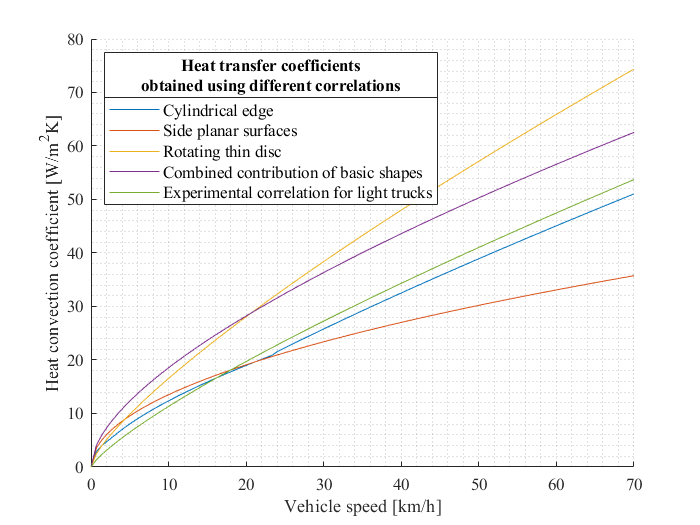

  htitle = get(leg1,'Title');
  set(htitle,'String',{'Heat transfer coefficients','obtained using different correlations'},'FontSize',10)
  grid minor

% xlim([V_f V_i])
% ylim([0 120])

## Single-Stop temperature analysis


% Material definition
% The constant "mat" is used in Mat_properties
%       %1= High Alloyed Martensitic Stainless Steel (Reference: AISI 410)
%       %2= High alloyed Ferritic Stainless Steel (Reference: AISI 446)
%       %3= MMC Aluminum Sinter material
%       %4= Titanium alloy (Reference: Ti6Al4)
%       %5= Carbon steel (Reference AISI 1060)

  brake_time = linspace(0,t_stop,length(omega)); 
  figure
  T_disc=zeros(length(brake_time),materials);
  Brake_torque_i=linspace(Brake_torque,0,length(brake_time));
  P_inst=Brake_torque_i.*omega;
  for mat=1:materials
     i=1;
      while i<=length(brake_time)
        %Initial Temperatures
        if i==1
          T_disc(i, mat)=60+273.15; %Input brake disc temperature [K]. Assumed or estimated value
        end
          T_air=22+273.15; %Air Temperature [K]
          T_film(i)=(T_air+T_disc(i))/2; %Film Temperature [K]
      
           Mat_properties;
          
           p=sqrt(k_metal*Cp_metal*rho_metal)*S_d/(sqrt(k_metal*Cp_metal*rho_metal)*S_d+sqrt(k_pad*Cp_pad*rho_pad)*S_p); %Heat Partition Coefficient Disc/Total
           %P_avg=Brake_torque*mean(omega)
           H_disc=P_inst(i)*p; %Heat transferred to the disc (partition of the total generated heat) [W]
           H_pad= P_inst(i)*(1-p); %Heat transferred to the pad (partition of the total generated heat) [W]
           
           
           %H_convection=(h_equiv(i)*(A_edge+A_holes+A_side*2))*(T_disc(i)-T_air); %Heat dissipated by convection [W]
            H_convection=(h_front(i)*(A_edge+A_holes)+(h_side(i)+h_rot(i))*A_side*2)*(T_disc(i)-T_air); %Heat dissipated by convection [W]
           H_radiation= 0.75*5.670367*10^-8*A_side*2*(T_disc(i)-T_air)^4; %Heat dissipated by radiation [W]
           
           Dt_brake(i)=(H_disc-H_convection-H_radiation)*t_stop/length(brake_time)/(rho_metal*V_disc*Cp_metal);
           
           T_disc(i+1,mat)=T_disc(i,mat)+Dt_brake(i);

           i = i + 1;
      end   
  end
  
  graph(1:materials)=plot(brake_time,T_disc((1:100),:)-273.15)

graph =   1×6 Line array:

    Line    Line    Line    Line    Line    Line


  yyaxis left,
  ylabel('Disc temperature during hard braking [°C]'), xlabel('Time [s]')
  set(gca, 'FontName', 'Times','FontSize',11)
%   ylim([0 220])
  
  yyaxis right
  graph(length(graph)+1)=plot(brake_time,P_inst,'r--')

graph =   1×7 Line array:

    Line    Line    Line    Line    Line    Line    Line


  ylabel('Power tranferred to the rotor [W]'), xlabel('Time [s]')
  set(gca, 'FontName', 'Times','FontSize',11,'YColor','r')
  leg2=legend(graph(1:materials),'AISI 410 stainless-steel','AISI 446 stainless steel',' Aluminum-based MMC','Ti6Al4 titanium alloy','AISI 1060 carbon steel','ASTM 40 gray cast iron','location','southoutside','FontSize',11)

leg2 =   Legend (AISI 410 stainless-steel, AISI 446 stainless steel,  Aluminum-based MMC, Ti6Al4 titanium alloy, AISI 1060 carbon steel, ASTM 40 gray cast iron) with properties:

         String: {'AISI 410 stainless-steel'  'AISI 446 stainless steel'  ' Aluminum-based MMC'  'Ti6Al4 titanium alloy'  'AISI 1060 carbon steel'  'ASTM 40 gray cast iron'}
       Location: 'southoutside'
    Orientation: 'vertical'
       FontSize: 11
       Position: [0.3423 0.1007 0.3511 0.2555]
          Units: 'normalized'

  Show all properties


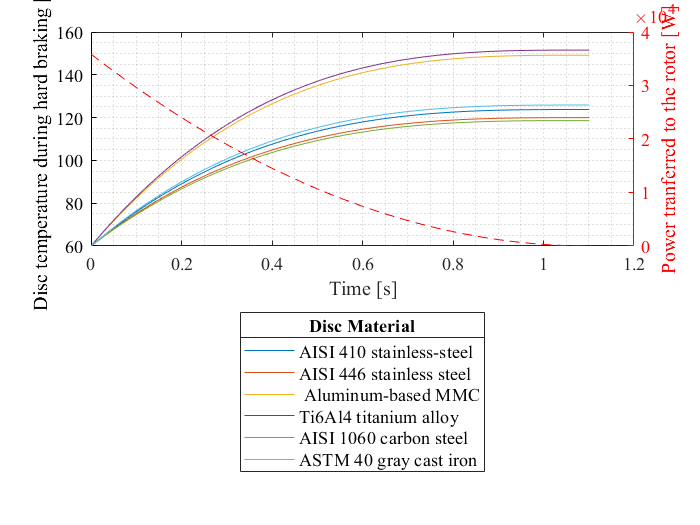

  htitle = get(leg2,'Title');
  set(htitle,'String','Disc Material')
  grid minor